clc; close all; clear all; 

load("Data\data_set.mat");
load("Data\wavelengths.mat");

X=data_set{:,22:end};
figure;
[coeff, score, latent, tsquared, explained, mu] = pca(X);

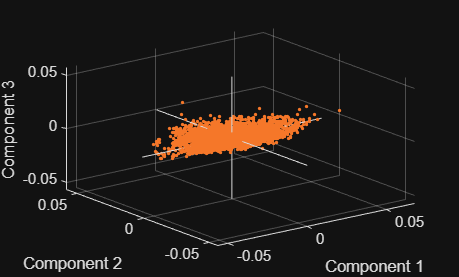


figure;
biplot(coeff(:,1:3), Scores=score(:,1:3));


var_visible= false; %set the visibility for the wavelength's contribution to the PCs
varl = findobj(gca,"Tag","varline");
varl.Visible=false;
varm = findobj(gca,"Tag","varmarker");
varm.Visible=false;

obsm = findobj(gca,"Tag","obsmarker");
%coordinates of points in biplot
bi_X= obsm.XData();
bi_Y= obsm.YData();
bi_Z= obsm.ZData();

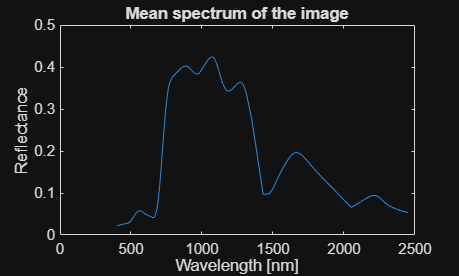

figure;
meanSpectra=mean(X);
plot(wavelengths, meanSpectra);
xlabel("Wavelength [nm]");
ylabel("Reflectance");
title("Mean spectrum of the image");

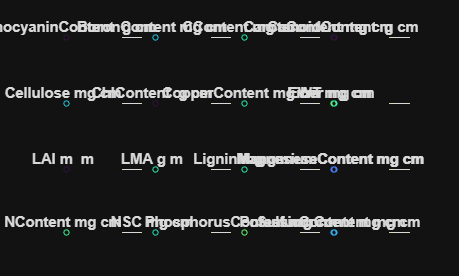

%Manual biplot taking values from biplot, so we can color it

figure;
column_names = data_set.Properties.VariableNames;
for i = linspace(2,21,20)
    nexttile;
    color_Column = data_set{:,i};
    
    rgb=vals2colormap(color_Column,'turbo',[min(color_Column),max(color_Column)]);
    scatter3(bi_X,bi_Y,bi_Z,10,rgb);
    hold on ;
    % plot3(coeff(:,1),coeff(:,2),coeff(:,3))
    % un-comment preceding line to show the vectors of the individual
    % wavelengths
    xlabel("PC 1");
    limits =[min(bi_X), max(bi_X)];
    xlim(limits);
    ylim(limits);
    zlim(limits);
    ylabel("PC 2");
    zlabel("PC 3");
    colormap('turbo');
    colorbar;
    title(extractBefore(column_names(i), "_"));
    % title(column_names(i))
    hold off
end

%Determine number of PCs needed with 95% of variation explained
idx = find(cumsum(explained)>95,1)

idx = 3